# Example 1: Fitting the parameters to the model using simulated data

## Background

A generalized SEIR model is used to simulate an epidemic breakout. Seven different states are considered in the following in a similar fashion as by [1], which is derived from SEIQR models [2] and has several similarities with mathematical models for SARS transmission, e.g. [3] :

- Susceptibles cases S(t)

- Insusceptible cases P(t)

- Exposed cases E(t)

- Infectious cases I(t)

- Quarantined cases Q(t)

- Recovered cases R(t)

- Dead cases D(t)

The parameters are as follows:

- alpha: protection rate

- beta: infection rate

- gamma: Inverse of the average latent time

- delta: rate at which infectious people enter in quarantine

- lambda: time-dependant recovery rate

- kappa: time-dependant mortality rate

The population is assumed constant, i.e. the births and natural death are not modelled. The cure rate and mortality rate are here time-dependent but they need some empirical coefficients to tune the time-dependency of these parameters.

The generalized SEIR model [1]  is:


$$\frac{\mathrm{d}S(t)}{\mathrm{d}t} = -\alpha S(t) -\beta \frac{S(t)I(t)}{N_{pop}}  \\
\frac{\mathrm{d}E(t)}{\mathrm{d}t} = -\gamma E(t) +\beta \frac{S(t)I(t)}{N_{pop}}  \\
\frac{\mathrm{d}I(t)}{\mathrm{d}t} = \gamma E(t) -\delta I(t)  \\
\frac{\mathrm{d}Q(t)}{\mathrm{d}t} = \delta I(t) -\lambda(t)Q(t) - \kappa(t) Q(t)  \\
\frac{\mathrm{d}R(t)}{\mathrm{d}t} = \lambda(t) Q(t) \\
\frac{\mathrm{d}D(t)}{\mathrm{d}t} = \kappa(t) Q(t) \\
\frac{\mathrm{d}P(t)}{\mathrm{d}t} = \alpha S(t) $$


### Recovery and mortality rates

The content presented hereafter is **not **proposed by [1]. Therefore, it can significantly differ from their work. In the following, the mortality rate $\kappa \left(t\right)$ is modelled as


$$\kappa \left(t\right)=\frac{\kappa_0 }{\exp \left(\left.\kappa_1 \left(t-\tau_{\kappa } \;\right)\right)\right)+\exp \left(\left.-\kappa_1 \left(t-\tau_{\kappa } \;\right)\right)\right)}$$


or as


$$\kappa \left(t\right)=\kappa_0 \;\exp \left(-{\left\lbrack \kappa_{1\;} \left(t-\tau_{\kappa } \right)\right\rbrack }^2 \right)\;$$


or as


$$\kappa \;\left(t\right)=\kappa_0 \;+\exp \left(-\kappa_1 \left(t+\tau_{\kappa } \;\right)\right)\;$$


where $\kappa_0 ,\;\kappa_1 \;\textrm{and}\;\tau_{\kappa }$ are parameters to be empricially determined. The parameters $\kappa_0$ and $\kappa_1$ have the dimension of the inverse of a time and $\tau_{\kappa }$ has the dimension of a time. 

The recovery rate $\lambda \left(t\right)$  is either modelled as


$$\lambda \;\left(t\right)=\frac{\lambda_0 }{1+\exp \left(\left.-\lambda_1 \left(t-\tau_{\lambda } \;\right)\right)\right)}$$


or as


$$\lambda \;\left(t\right)=\lambda_0 \;+\exp \left(-\lambda_1 \left(t+\tau_{\lambda } \;\right)\right)\;$$


where ${\lambda \;}_0 ,\;\lambda_1 \;\textrm{and}\;\tau_{\lambda }$ are parameters to be empricially determined. The parameters $\lambda_0$ and $\lambda_1$ have the dimension of the inverse of a time and $\tau_{\lambda }$ has the dimension of a time.

 The choice of best approximation for $\lambda \;\left(t\right)$ and $\kappa \;\left(t\right)$ is done automatically inside the function fit_SEIRQDP based on a preliminary assessment of the recovery rate and the mortality rate. The idea behind these functions is that the mortality rate should become close to zero (or a constant value $\kappa_0$)  at time increases while the recovery rate converges toward a constant value $\lambda_0$.

### Numerical solutions

I also decided to re-write the system of ODEs in a matrix form for the sake of clarity:


$$\frac{\textrm{dY}}{\textrm{dt}}=A*Y+F$$


where 


$$Y={\left\lbrack S,E,I,Q,R,D,P\right\rbrack }^{\top } \;$$



$$A=\left\lbrack \begin{array}{cccccccc}
-\alpha  & 0 & 0 & 0 & 0 & 0 & 0 & \\
0 & -\gamma  & 0 & 0 & 0 & 0 & 0 & \\
0 & \gamma  & -\delta  & 0 & 0 & 0 & 0 & \\
0 & 0 & \delta  & -\kappa \left(t\right)-\lambda \left(t\right) & 0 & 0 & 0 & \\
0 & 0 & 0 & \lambda \left(t\right) & 0 & 0 & 0 & \\
0 & 0 & 0 & \kappa \left(t\right) & 0 & 0 & 0 & \\
\alpha  & 0 & 0 & 0 & 0 & 0 & 0 & 
\end{array}\right\rbrack$$



$$F=S\left(t\right)\cdot \;I\left(t\right)\cdot \left\lbrack \begin{array}{c}
-\frac{\beta }{N_{\textrm{pop}} }\\
\frac{\beta }{N_{\textrm{pop}} }\\
0\\
0\\
0\\
0\\
0
\end{array}\right\rbrack$$


The equation $\frac{\textrm{dY}}{\textrm{dt}}=A*Y+F$ is then solved using the classic 4th order Runge-Kutta method.

### Important note

The initial number of exposed $E_0$ and infectious $I_0$ is not known. In the present version, these values are not estimated by least-square fit altough the choice of $E_0$ and $I_0$ could affect the godness of the fit and the estimated parameters.

### References

[1] Peng, L., Yang, W., Zhang, D., Zhuge, C., & Hong, L. (2020). Epidemic analysis of COVID-19 in China by dynamical modeling. *arXiv preprint arXiv:2002.06563*.

[2] Feng, Z., & Thieme, H. R. (1995). Recurrent outbreaks of childhood diseases revisited: the impact of isolation. *Mathematical Biosciences*, *128*(1-2), 93-130.

[3] Lipsitch, M., Cohen, T., Cooper, B., Robins, J. M., Ma, S., James, L.,  ... & Fisman, D. (2003). Transmission dynamics and control of severe acute respiratory syndrome. *Science*, *300*(5627), 1966-1970.

## Example

### Initialisation

Case of an imaginary epidemy outbreak that took place on 2010-01-01. The simulation time is set to 6 months.

clearvars;close all;clc;
addpath('./functions'); % add the folder function to the path
% Time definition
dt = 0.1; % time step
time1 = datetime(2010,01,01,0,0,0):dt:datetime(2010,06,01,0,0,0);
N = numel(time1);
t = [0:N-1].*dt;

### Generate the data

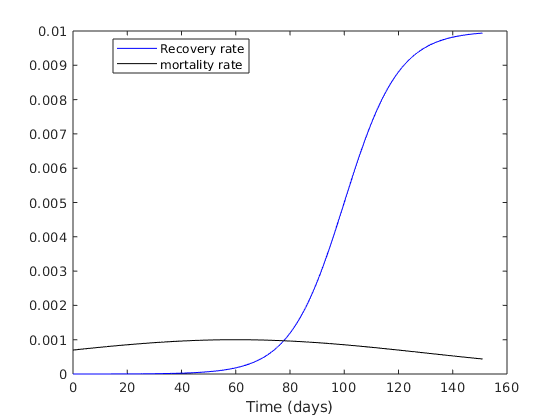

Npop= 60e6; % population (60 millions)
Q0 = 200; % Initial number of infectious that have bee quanrantined
I0 = Q0; % Initial number of infectious cases non-quarantined
E0 = 0; % Initial number of exposed
R0 = 10; % Initial number of recovereds
D0 = 10; % Initial number of deads
alpha = 0.08; %  protection rate
beta = 0.9; %  infection rate
gamma= 0.2; % inverse of average latent time
delta= 0.5; % rate at which infectious people enter in quarantine
Lambda = [0.01 0.1 100]; % cure rate (time dependant)
Kappa =  [0.001 0.01,60]; % mortality rate (time dependant)

% Choice of a particular form for lambda(t)
lambdaFun0 = @(a,t) a(1)./(1+exp(-a(2)*(t-a(3))));
kappaFun0 = @(a,t) a(1).*exp(-(a(2)*(t-a(3))).^2);

[S,E,I,Q,R,D,P] = SEIQRDP(alpha,beta,gamma,delta,Lambda,Kappa,Npop,E0,I0,Q0,R0,D0,t,lambdaFun0,kappaFun0);

figure
plot(t,lambdaFun0(Lambda,t),'b',t,kappaFun0(Kappa,t),'k')
legend('Recovery rate','mortality rate','location','best');
xlabel('Time (days)')

set(gcf,'color','w')

### Fit the data

The fitting is done using the time histories of the number of quarantined $Q\left(t\right)$, recovered $R\left(t\right)$ and deads $D\left(t\right)$ only. The number of exposed,  susceptible, insusceptible and infectious is computed in the model but not used as target.

lambdaGuess = [0.01 0.5 0.1];
kappaGuess = [0.01 0.1,10];
alphaGuess = 0.05;
betaGuess = 0.7;
deltaGuess = 0.2;
gammaGuess = 0.3;
guess = [alphaGuess,betaGuess,deltaGuess,gammaGuess,lambdaGuess,kappaGuess]; % initial guess

[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,lambdaFun,kappaFun0] = fit_SEIQRDP(Q,R,D,Npop,E0,I0,time1,guess,'Display','off');
[S1,E1,I1,Q1,R1,D1,P1] =...
    SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,Q0,R0,D0,t,lambdaFun,kappaFun0);

### Comparison beween fitted and generated time histories

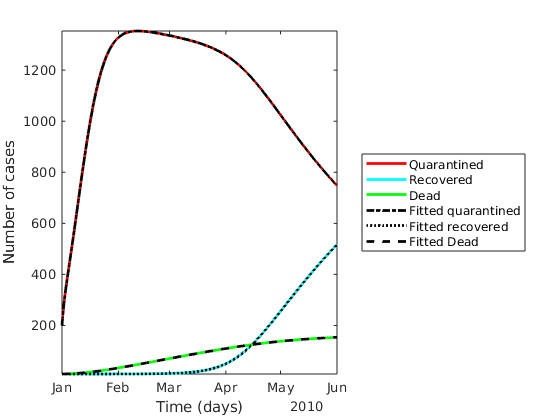

figure
clf;close all;
plot(time1,Q,'r',time1,R,'c',time1,D,'g','linewidth',2);
hold on
plot(time1,Q1,'k-.',time1,R1,'k:',time1,D1,'k--','linewidth',2);
% ylim([0,1.1*Npop])
ylabel('Number of cases')
xlabel('Time (days)')
leg = {'Quarantined','Recovered','Dead','Fitted quarantined','Fitted recovered','Fitted Dead'};
legend(leg{:},'location','eastoutside')
set(gcf,'color','w')
axis tight

### Case where the recovered (R) and quarantined (Q) data are not available separately

The  number of qarantined Q(t) and recovered cases R(t)  is unknwon, However,  Q(t) + R(t) is known.

guess = [alphaGuess,betaGuess,deltaGuess,gammaGuess,lambdaGuess,kappaGuess]; % initial guess

[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,lambdaFun,kappaFun] = ...
    fit_SEIQRDP(Q+R,[],D,Npop,E0,I0,time1,guess,'Display','off');

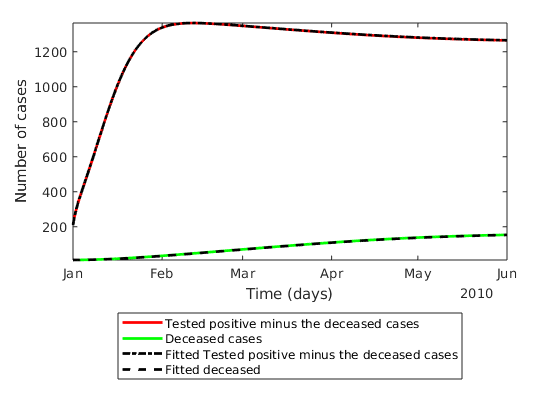


[S1,E1,I1,Q1,R1,D1,P1] =...
    SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,...
    Npop,E0,I0,Q0,R0,D0,t,lambdaFun,kappaFun);

figure
clf;close all;
plot(time1,Q+R,'r',time1,D,'g','linewidth',2);
hold on
plot(time1,Q1+R1,'k-.',time1,D1,'k--','linewidth',2);
% ylim([0,1.1*Npop])
ylabel('Number of cases')
xlabel('Time (days)')
leg = {'Tested positive minus the deceased cases','Deceased cases','Fitted Tested positive minus the deceased cases','Fitted deceased'};
legend(leg{:},'location','southoutside')
set(gcf,'color','w')
axis tight